# **Vision Artificial. GIEC.**

# **	Sistemas de Vision Artificial. GIC.**

**	Miguel Angel Garcia, Juan Manuel Miguel, Sira Palazuelos. **

**  Departamento de Electrónica. Universidad de Alcalá.**

# Tema 5: ejercicio 01 - Calibración de una cámara

**Nota**: el tamaño del cuadrado del tablero de ajedrez es de **21 milímetros**.

clc
clear all:
close all;

Step 1) Load data set.

image_num = 3;
image_name = sprintf('checkerboard_pattern/image%d.png',image_num);
image = imread(image_name);
imageUndistorted = undistortImage(image,cameraParams);
imshowpair(image,imageUndistorted,'montage')  

Se pide:

         1. Usa la aplicación [**Camera Calibrator**](https://es.mathworks.com/help/vision/ref/cameracalibrator-app.html) para estimar los parámetros intrínsecos, extrínsecos y de distorsión de la cámara. Escriba `cameraCalibrator` en la línea de comandos de Matlab o selecciónelo en la pestaña de Aplicaciones (APPS) de Matlab. Siga las instrucciones de este enlace para realizar la calibración: [https://es.mathworks.com/help/vision/ug/single-camera-calibrator-app.html](https://es.mathworks.com/help/vision/ug/single-camera-calibrator-app.html)  **NOTA**: utilice una webcam y el patrón del tablero de ajedrez o directamente las imágenes de la carpeta "`/chessboard_pattern`". 

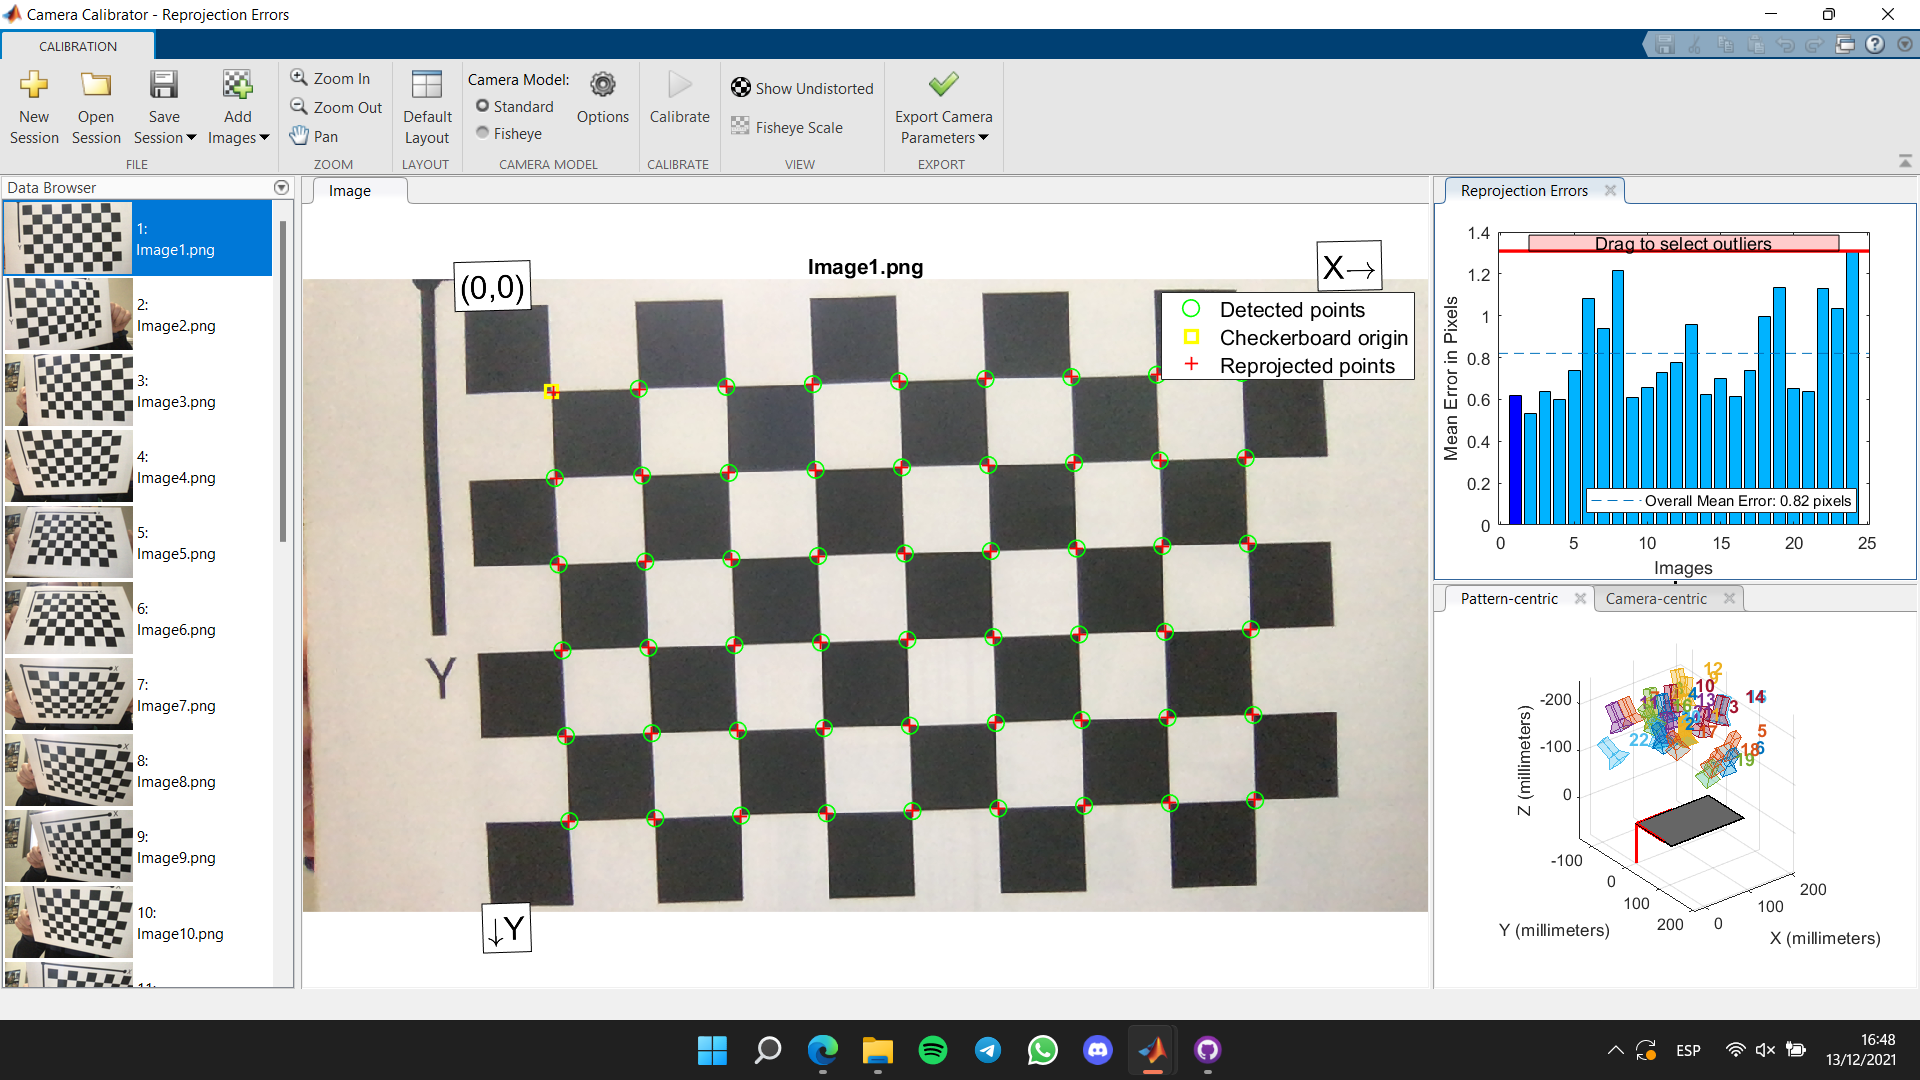

         2. Una vez que se ha realizado una calibración correcta, exporte los parámetros de calibración al espacio de trabajo (Workspace) con el nombre `cameraParams`.

**Posteriormente, hemos exportado los parámetros de la cámara al *****workspace*****. **

**Para no tener que calibrar la cámara cada vez que abrimos el ejercicio, hemos guardado los parámetros de la cámara utilizando:**

- `save 'cameraParams.mat' cameraParams `**si se hace en la *****Command Window*****.**

- `save('cameraParams.mat', cameraParams) `**si se ejecuta en un bloque de código.**

         3. Obtenga la matriz de parámetros intrínsecos e identifique los distintos parámetros. Cargue una de las imágenes utilizadas para la calibración y obtebga los parámetros extrínsecos de esta imagen. ¿si cargase otra imagen diferente cambiaría alguno de los parámetros intrínsecos o extrínsecos? justifique la respuesta.

         4. Cargue una de las imágenes utilizadas para la calibración y obtenga la imagen no distorsionada con la función `undistorsionImage. `Proyecte los puntos de una pirámide 3D en esta imagen no distorsionada usando la función `worldToImage`. Nota: uno de los vértices de la pirámide debe estar situado en el punto de las coordenadas del mundo (X=0,Y=0,Z=0) y el tamaño de la base de la pirámide debe ocupar cuadrados del patrón del tablero de ajedrez y la altura debe ser 1.5 veces la longitud de un lado de la base.

Nota: la matriz de parámetros intríonsecos es: